Controllo se è rimasta aperta la porta seriale

if( exist('STM32_ser') );
    delete(STM32_ser);
    clear STM32_ser;
end

Connetto alla seriale

porte_libere = serialportlist("available")

porte_libere = "COM8"

STM32_ser = serialport(porte_libere(end), 1000000, Timeout=2);
configureTerminator(STM32_ser,"CR");

3.3 * cast(5000,'double')/cast(intmax('uint16'), 'double');

Acquisisco il segnale in loop:

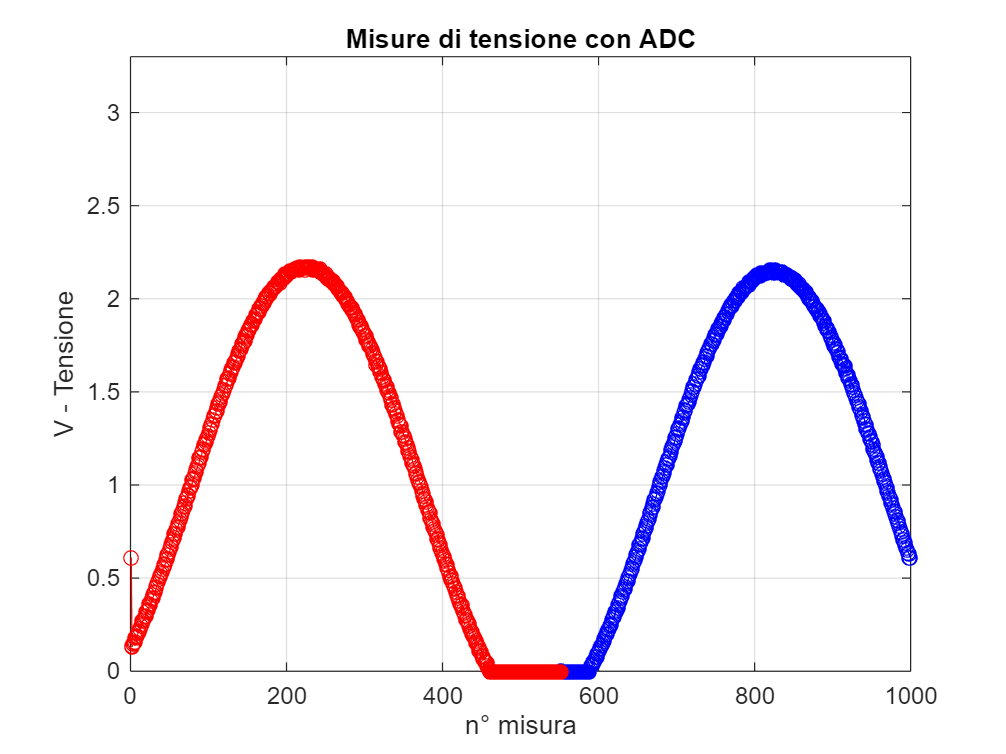

Index exceeds array bounds.

figure

% lunghezza singlo pacchetto di dati
l = 1000;

while 1
    STM32_ser.flush;
    STM32_ser.write('?','char');


    vettore = read(STM32_ser, l+1, 'uint16');
    index = l+1 - vettore(l+1);
    
    if index == 0
        message("Errore")
        continue
    end

    for i=1:l
       vettore(i) = 3.3 * vettore(i)/cast(intmax('uint16'), 'double');
    end

    %plot(vettore(1:100), 'b--o')
    plot((l-index+1):l, vettore(1:index), 'b--o', 1:(l-index+1),vettore(index:l), 'r-o');
    title('Misure di tensione con ADC');
    ylabel("V - Tensione");
    ylim([0,3.3]);
    xlabel('n° misura');
    box on;
    grid on;
    %drawnow;

end